load("sampleEEGdata.mat")

srate = 500;
time = -0.1:1/EEG.srate:0.1;

s = 5/(2*pi*30);
g_kernel = exp((-time.^2)/(2*s^2))/30;

signal = squeeze(EEG.data(47,:,1));

figure;
subplot(411)
plot(EEG.times, signal)
title("Raw EEG Data")

subplot(412)
plot(time,g_kernel)

subplot(413)

hk_size = ceil((length(g_kernel) - 1)/2);
conv_result = zeros(1,length(signal) + length(g_kernel) - 1);


for i = 1:length(signal)
    conv_result(i) = sum(signal(max(1, i-length(g_kernel)+1):i) .* g_kernel(end:-1:max(1, length(g_kernel)-i+1)));
end


conv_result = conv_result(hk_size:end - hk_size)

conv_result =     0.0470    0.0703    0.0469   -0.1443   -0.1328   -0.2906   -0.4482   -0.3591   -0.3279   -0.2861   -0.2719   -0.1872   -0.1596   -0.0862   -0.0392    0.0028    0.0565    0.0725    0.0872    0.0973    0.1066    0.1111    0.1144    0.1170    0.1183    0.1189    0.1193    0.2696    0.4517    0.6702    0.9290    1.2306    1.5749    1.9609    2.3840    2.8385    3.3155    3.8051    4.2966    4.7779    5.2378    5.6651    6.0498    6.3832    6.6576    6.8672    7.0080    7.0777    7.0748    6.9999


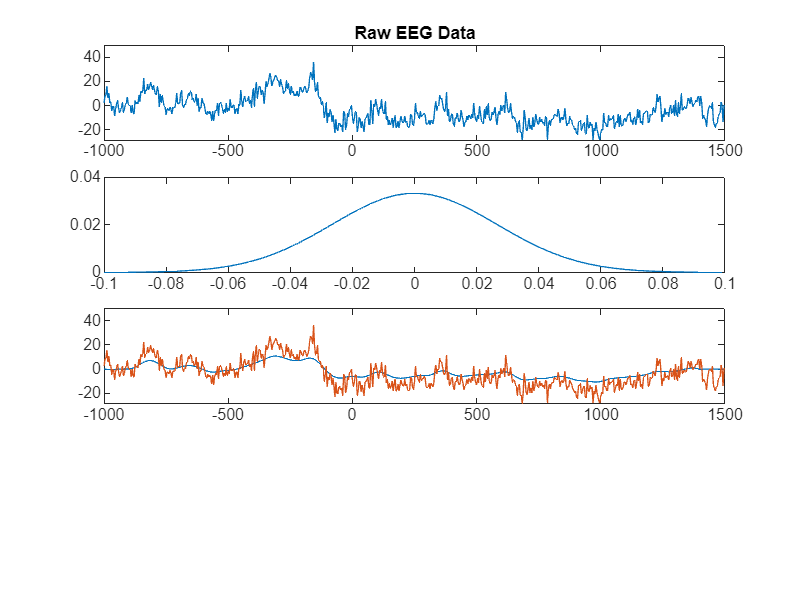


plot(EEG.times, conv_result)
hold on
plot(EEG.times, signal)